# data loading

clearvars;
FL.SR = 1000;% Sampling Rate (Hz), FluoLescence
const.ch = 2;% 6 ch rec.
const.span = 99;%for smooth
const.DefaultPath = 'C:\Users\Kenzo Kosugi\Desktop\mouseEEG\202303_2nd series\';%'C:\Users\pdp\Documents\data';

[const.FileName, const.PathName] = uigetfile('*.bin', 'Select bin file (rec.: 2 ch, 1kHz)', const.DefaultPath);
if isequal(const.FileName, 0), return, end
const.FN_binData = fullfile(const.PathName, const.FileName);                    %h FileName

raw_data = readmulti_DBL(const.FN_binData, const.ch); %readmulti_DBLは2015年に高田先生が作成したオリジナルの関数
% raw_dataの1列目がEEG data, 2列目がEMG daga
eeg = raw_data(:,1);

srate = FL.SR; % sampling rate
npnts = size(raw_data,1); % time points (全データ数)             % Time_total = npnts
time = (npnts - 1) / srate; % time (second)
timevec = linspace(0,time,npnts); % time vector (vector)

eeg = eeg * 1000; % Converts EEG voltage values from mV to uV
ABS_eeg = abs(eeg); % micro-volt(uV)
Time_total = npnts;

% plot
% figure;
% plot(timevec, eeg, 'k');
% xlabel('time(second)'), ylabel('amplitude(micro volt)')

## This block of code AUTOMATICALLY determines the baseline, lower threshold, and upper threshold values

Start_Value = 100;                                              %uV
Tally = 0;                                                      %Placeholder variable
Percent = 0;                                                    %Placeholder variable
while Percent < 0.97 && Start_Value <= 130                      % 0.97 = the set percentage of data points that MUST be below threshold value
    for a = 1:2000000                                           % Scan window for determing lower threshold (1 step = 0.002 seconds) これで最初の約１時間のデータ量ということになる
        if ABS_eeg(a) < Start_Value                             % Logic loop for determining threshold
            Tally = Tally + 1;                                  % Not relevant
        else
        end
    end
    Start_Value = Start_Value + 5;                              % Increases the lower threshold by 5 uV each pass through the loop
    Percent = Tally/a;                                          % Current percentage of data points that are below the threhsold value
    Tally = 0;                                                  % Not relevant
end

fprintf('The baseline EEG value was set at %.0f µV \n', Start_Value-5)

The baseline EEG value was set at 100 µV 


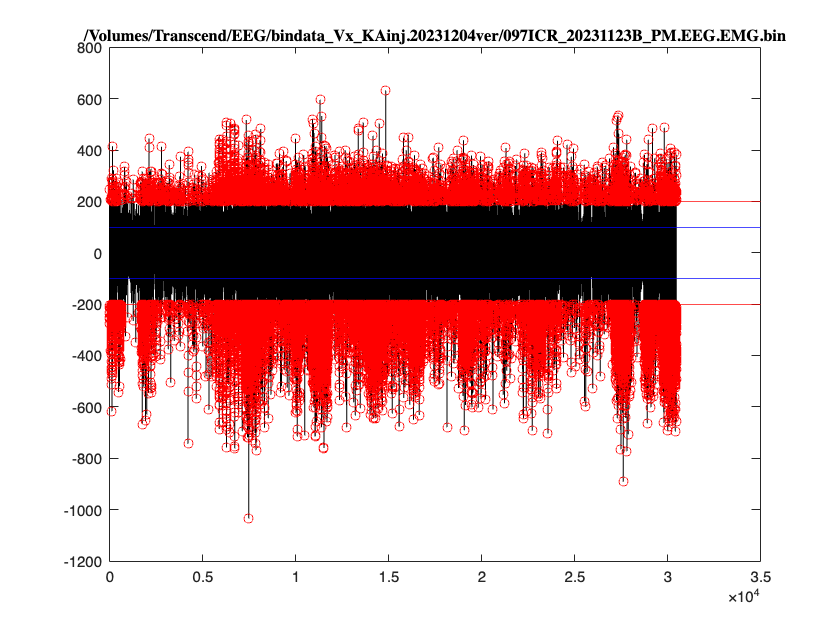

Baseline = Start_Value-5;                                       % This is the baseline value in uV
Lower_Threshold = 2*Baseline;                                   % This is the lower threshold in uV (2X the baseline)

Upper_Threshold = 1500;                                         % This is the upper threshold, set at 1500 uV
% Lower_Threshold_Adj = Lower_Threshold*0.001;                    % This converts the lower threshold to mV
% Upper_Threshold_Adj = Upper_Threshold*0.001;                    % This converts the upper threshold to mV

% Peak Finding Algorithm ----------------------------------------------------------------------
[spikes,position,width,prom] = findpeaks(ABS_eeg,'MinPeakDistance',50, 'MinPeakProminence', 0.2, 'MinPeakHeight', Lower_Threshold, 'MaxPeakWidth', 100);      % Finds positive EEG spikes
peaks = zeros(1,length(spikes));                                % This variable contains all the peak amplitudes
location = zeros(1,length(spikes));                             % This variable contains all the peak locations in seconds
% DateTime = zeros(1,length(spikes));                             % This variable contains the date and time associated with each peak

for i = 1:length(spikes)
    if spikes(i) > 2*Baseline && spikes(i) < Upper_Threshold   % Determines if peak is > threshold
        peaks(1,i) = spikes(i);                                 % Saves peak amplitudes as new variable
        location(1,i) = position(i);                            % Saves peak locations (seconds) as new variable
        % DateTime(1,i) = datenum(DateTime_Vector(1,position(i)));% Saves date/time for each peak
    else
        peaks(1,i) = 0;                                         % Disregards peaks < 2X baseline or > 1500 uV
        location(1,i) = 0;                                      % Disregards location of peaks that dont satisfy above criteria
        % DateTime(1,i) = datenum(DateTime_Vector(1,position(i))); % Saves date and time of false peaks
    end
end

peaks_2 = zeros(1,length(peaks));                               % Placeholder variable
location_2 = zeros(1,length(location));                         % Placeholder variable
spike_count = 0;                                                % Placeholder variable
for p = 1:length(peaks)                                         % Logic loop that converts to positive AND negative values
    if peaks(1,p) > 0                                           % Peaks with a value > 0 are saved
        peaks_2(1,p) = eeg(position(p));                 % Saves true peak amplitude (mV) with negative values present
        location_2(1,p) = location(p);                          % Saves true peak location
        spike_count = spike_count + 1;                          % Counts the number of true peaks
    else
    end
end

% Remove false peaks from "peaks_4" variable
peaks_3 = transpose(peaks_2);                                   % Transposes peaks_2 array
location_2 = transpose(location_2);                             % Transposes location_2 array
% DateTime = transpose(DateTime);                                 % Transposes DateTime array
aa = size(peaks_3,1);                                           % Placeholder Variable
bb = true(aa,1);                                                % Logic Statement placeholder variable
for cc=1:aa
    if peaks_3(cc,1) ~= 0                                       % Removes false peaks
        bb(cc,1) = false;                                       % Logic statement
    end
end
peaks_3(bb,:) = [];                                             % Rewrites variable with ONLY TRUE PEAKS
location_2(bb,:) = [];                                          % Rewrites variable with ONLY TRUE PEAK LOCATIONS
% DateTime(bb,:) = [];                                            % Rewrites variable with ONLY TRUE PEAK DATES AND TIMES

% Plotting EEG Data - Seconds Time Scale -----------------------------------------------------------------------

% Time = transpose(0:Time_seg:Time_total);                    % Creates a time variable in seconds
figure                                                      % Creates a new figure window
plot(timevec,eeg,'k-')                % Plots RAW EEG data trace in seconds time scale
hold on
plot(timevec(location_2),peaks_3,'ro')                               % Plots red circles that mark detected peaks
% leg = legend(strcat("Record ",int2str(Record),", Lead ",int2str(Record)," ",info.SignalLabels(Lead)));  % Creates a legend on the figure
% set(leg,'AutoUpdate','off')                                 % Adjusts legned for proper display
% xlim([0 250])                                               % Sets X-axis window from 0 to 250 seconds
% ylim([-1.5 1.5])                                            % Sets Y-axis window from -1.5 to 1.5 mV
% xlabel('Time (s)')                                          % Creates X-axis label
% ylabel('Voltage (mV)')                                      % Creates Y-axis label
% title(strcat(Timeframe_String,"-", 'Hour EEG Data for Mouse'," ", Mouse_Number,' - Seconds Time Scale'))    % Creates a title for the figure

title(const.FN_binData, 'Interpreter', 'none','fontname', '游ゴシック')
yline(Lower_Threshold, 'r-')                           % Creates a red line at the lower threshold value (positive)
yline(-Lower_Threshold, 'r-')                          % Creates a red line at the lower threshold value (negative)
yline(Baseline, 'b-')                                  % Creates a blue line at the baseline value (positive)
yline(-Baseline, 'b-')                                 % Creates a blue line at the baseline value (negative)


% Seizure Detector -----------------------------------------------------------------------------
Interval = zeros(2,length(location_2));                      % Placeholder Variable
Int_Length = length(location_2(:,1));                        % Determines length of Peak_Data variable

for q = 1:Int_Length-1
    Interval(1,q) = location_2(q+1) - location_2(q);       % Calculates distance between spikes (msec)
    Interval(2,q) = location_2(q);                         % Saves location (s) of spikes
end

Interval = Interval / 1000;  % convert sampling rate (in this case, 1000Hz. So equivalent to msec) to second

Status = zeros(2,length(Interval));                         % Placeholder variable
for r = 1:length(Interval)
    if Interval(1,r) > 0.6                                  % Loop exlcudes spikes more than 2 seconds apart from being part of the same seizure
        Status(1,r) = 0;                                    % If true (> 2 seconds apart), the iterating spike chain breaks
        Status(2,r) = Interval(2,r);                        % Variable that saves the legnth of time between spikes
    else
        Status(1,r) = 1;                                    % If false (< 2 seconds apart), the spike chain continues to iterate
        Status(2,r) = Interval(2,r);                        % Variable that saved the length of time between spikes
    end
end

Seizure_Record = zeros(length(Status),5);                   % Placeholder variable
Spike_Tally = 0;                                            % Placeholder variable
Seizure_Length = 0;                                         % Placeholder variable

for s = 1:length(Status)
    if Status(1,s) == 1                                     % If the spikes are less than 5 seconds apart, the loop continues
        Spike_Tally = Spike_Tally + 1;                      % Counts the number of spikes in each seizure
        Seizure_Length = Seizure_Length + Interval(1,s);    % Records the growing length of the seizure
    else                                                    % If spikes are greater than 5 seconds apart, the loop breaks
        Spike_Tally = Spike_Tally + 1;                      % Memory variable. DO NOT CHANGE!
        Seizure_Record(s,1) = Spike_Tally;                  % Saves the number of spikes in the last seizure
        Seizure_Record(s,2) = Seizure_Length;               % Saves the length of the last seizure
        Seizure_Record(s,3) = Interval(2,s-Spike_Tally+1);  % Saves the beginning location of the seizure
        Seizure_Record(s,4) = Seizure_Record(s,2) + Seizure_Record(s,3);% Saves the ending location of the seizure
        Seizure_Record(s,5) = location_2(s,1);               % Saves the date and time associated with the beginning of the seizure
        Seizure_Record(s,6) = Seizure_Record(s,4) - Seizure_Record(s,3);
        Spike_Tally = 0;                                    % Resets the spike counter to 0 for the next seizure
        Seizure_Length = 0;                                 % Resets the seizure length to 0 for the next seizure
    end
end

w = size(Seizure_Record,1);                                 % Determines the number of seizures saved
x = false(w,1);                                             % Logic statement placeholder variable
for y=1:w
    if Seizure_Record(y,2) == 0                             % Removes single spikes that aren't part of an seizure
        x(y) = true;                                        % Logic statement for removing false seizures
    end
end
Seizure_Record(x,:) = [];                                   % Saves Seizure_Record variable with single spikes removed

g = size(Seizure_Record,1);                                 % Determines the number of seizures saved
h = true(g,1);                                              % Logic statement placeholder variable
for z=1:g                                                   % Loop removes seizures with duration less than 10 seconds
    if Seizure_Record(z,2) > 6                              % '10' = minimum seizure length in seconds
        h(z) = false;                                       % Logic statement for above loop
    end
end
Seizure_Record(h,:) = [];                                   % Saves Seizure_Record variable with ONLY TRUE seizures

hours = time/60/60;
interictal_spikes = length(spikes) - sum(Seizure_Record(:,1));
dense_spike_count = interictal_spikes/hours;
Seizure_count = size((Seizure_Record),1);
dense_seizure_count = Seizure_count/hours;
Total_seizure_duration = sum(Seizure_Record(:,6));          % total seizure duration
dense_seizure_duration = Total_seizure_duration/hours;

Results = zeros(6,1);
Results(1) = interictal_spikes;
Results(2) = dense_spike_count;
Results(3) = Seizure_count;
Results(4) = dense_seizure_count;
Results(5) = Total_seizure_duration;
Results(6) = dense_seizure_duration;